clear;
close all;
clf

Obrim la imatge i binaritzem amb un llindar fix:

I = rgb2gray(imread('Joc_de_caracters.jpg'));
BI = I < 128; % lletres estan en negre

Obtenim la llista dels píxels que conformen cadascun dels caràcters segmentats:

CC = bwconncomp(BI);

Mesurem algunes propietats descriptores de forma (fortament dependents de la mida de l’objecte):

props = regionprops(CC,'Area','MajorAxisLength','MinorAxisLength');

Cal passar de llista a taula, per això construïm una taula de mesures o taula d’observacions:

X = [props.Area; props.MajorAxisLength; props.MinorAxisLength;]';

Construïm el output o resultat que voldríem obtenir a partir de les entrades X (taula de mesures):

OUT = {'0' '1' '2' '3' '4' '5' '6' '7' '8' '9' 'B' 'C' 'D' 'F' 'G' 'H' 'J' 'K' 'L' 'M' 'N' 'P' 'R' 'S' 'T' 'V' 'W' 'X' 'Y' 'Z'};

Construcció d'un classificador. Sense entrar en detalls, ni consideracions d’overfiting, farem servir un model/funció de classificació anomenada *TreeBagger* que ens retorna una variable anomenada *Classifier*, variable que una posterior funció de predicció farà servir per predir el resultat de noves observacions. El vector OUT és el resultat que el *TreeBagger* haurà d’aprendre a “endevinar” a partir de les observacions X.

Classifier = TreeBagger(100,X,OUT');

Ara cal comprovar que tan bo és el classificador, repetint el procediment de mesura amb una nova imatge de test.

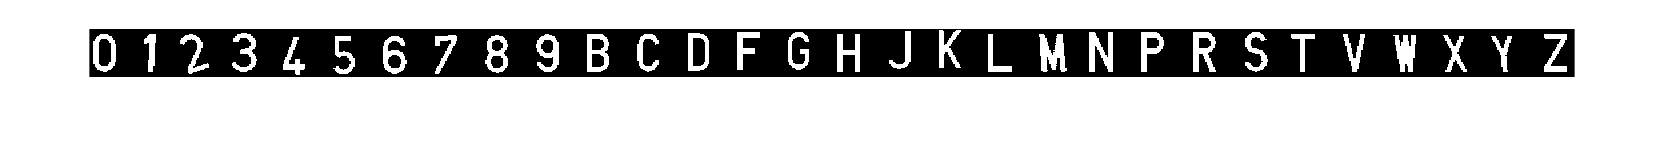

I = rgb2gray(imread('Joc_de_caracters_deformats.jpg'));
BI = I < 128; % separem el background
figure;imshow(BI);

CC = bwconncomp(BI);

props = regionprops(CC,'Area','MajorAxisLength','MinorAxisLength');
X = [props.Area; props.MajorAxisLength; props.MinorAxisLength;]'; 

Amb la variable *Classifier* i la funció *Predict* intentem endevinar quin caràcter és cadascun (*label*) i quina puntuació té la classificació (*score*).

[label,score] = predict(Classifier,X);

% mostrem el resultat mes probable i la seva puntuació (score)
table(Classifier.ClassNames,label,max(score,[],2),'VariableNames',{'Name','Label','Score'})

ans = 30×3 table
    Name     Label    Score
    _____    _____    _____

    {'0'}    {'0'}    0.62 
    {'1'}    {'1'}    0.38 
    {'2'}    {'2'}    0.39 
    {'3'}    {'5'}    0.16 
    {'4'}    {'4'}    0.64 
    {'5'}    {'5'}    0.47 
    {'6'}    {'6'}    0.58 
    {'7'}    {'7'}    0.63 
    {'8'}    {'8'}     0.6 
    {'9'}    {'9'}    0.62 
    {'B'}    {'B'}    0.64 
    {'C'}    {'C'}    0.59 
    {'D'}    {'D'}    0.62 
    {'F'}    {'F'}    0.64 
    {'G'}    {'G'}    0.63 
    {'H'}    {'H'}    0.73 


Analitzeu quines observacions/característiques són més les més influents per classificar les lletres. També podeu comparar resultats utilitzant altres classificadors.